# Infinite PEPS (iPEPS): corner transfer matrix (CTM)

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we implement the symmetric variant of the corner transfer matrix renormalization group (CTMRG) for the infinite PEPS on a square lattice, with a 1 x 1 unit cell.

## PEPS representation of the classical Ising model

Here we consider the classical Ising model on a square lattice in the thermodynamic limit. We can construct an iPEPS (which is a *quantum* state) that can describe the *classial* partition function, following the recipe given in Eqs. (32)–(35) and Fig. 27 of Orus2014 [[R. Orús, Ann. Phys. **349**, 117 (2014)](https://www.sciencedirect.com/science/article/pii/S0003491614001596?via%3Dihub)].

The iPEPS represents an unnormalized state $| \psi (\beta ) \rangle = e^{-\beta \hat{H}/2} \mathop{\otimes}_i ( |\uparrow\rangle_i + |\downarrow\rangle_i )$, where a product state is evolved in imaginary time via the Hamiltonian $\hat{H} = - \sum_{\langle ij \rangle} \hat{\sigma}_{z,i} \hat{\sigma}_{z,j}$. Here $i$ and $j$ are the lattice site coordinates. Note that here we use a different normalization of $|\psi (\beta)\rangle$, compared to Eq. (32) of Orus2014. Then the squared norm of the state, $\langle \psi (\beta) | \psi (\beta) \rangle$, equals to the partition function of the classical Ising model.

We can construct a rank-5 tensor for the 1 x 1 unit cell of the PEPS, as explained in Fig. 27 of Orus2014.

clear
beta = 0.4; % inverse temperature

% rank-3 tensor in the second line of Fig. 27 of Orus2014
M1 = zeros(2,2,2); % leg order: down-up-right (or left)
M1(:,:,1) = sqrt(cosh(beta/2))*eye(2);
M1(:,:,2) = sqrt(sinh(beta/2))*diag([1;-1]);
M1 = permute(M1,[1 3 2]);

% contract four rank-3 tensors
M = M1;
for itl = (1:3)
    M = contract(M,2+itl,2+itl,M1,3,1);
end
% project the last leg onto |up>+|down>
M = contract(M,6,6,[1;1],2,1);
% permute so that the legs are left-up-physical-down-right
M = permute(M,[2 3 1 4 5]);

By construction, the tensor `M` is symmetric under exchanging bond legs.

By using the symmetric CTMRG, we can compute the squared norm of the iPEPS per site, $\langle \psi(\beta) | \psi(\beta) \rangle^{1/N}$, which leads to the free energy per site, $F = - \beta^{-1} \ln (\langle \psi(\beta) | \psi(\beta) \rangle^{1/N})$. Below we will compare the CTMRG result of $F$ with the exact one,


$$- \beta F = \frac{\ln 2}{2} + \frac{1}{2\pi} \int_0^\pi \mathrm{d} x \, \ln \left[ \cosh^2 2\beta + \sinh 2\beta \sqrt{ \sinh^2 2\beta + \sinh^{-2} 2\beta - 2 \cos 2x} \right] ,$$


where the integration can be performed numerically. Here the equation is taken from the [Wikipedia page on Onsager's solution of the square-lattice Ising model](https://en.wikipedia.org/wiki/Square_lattice_Ising_model).

For a range of inverse temperature, we compute and plot the exact results of the free energy per site.

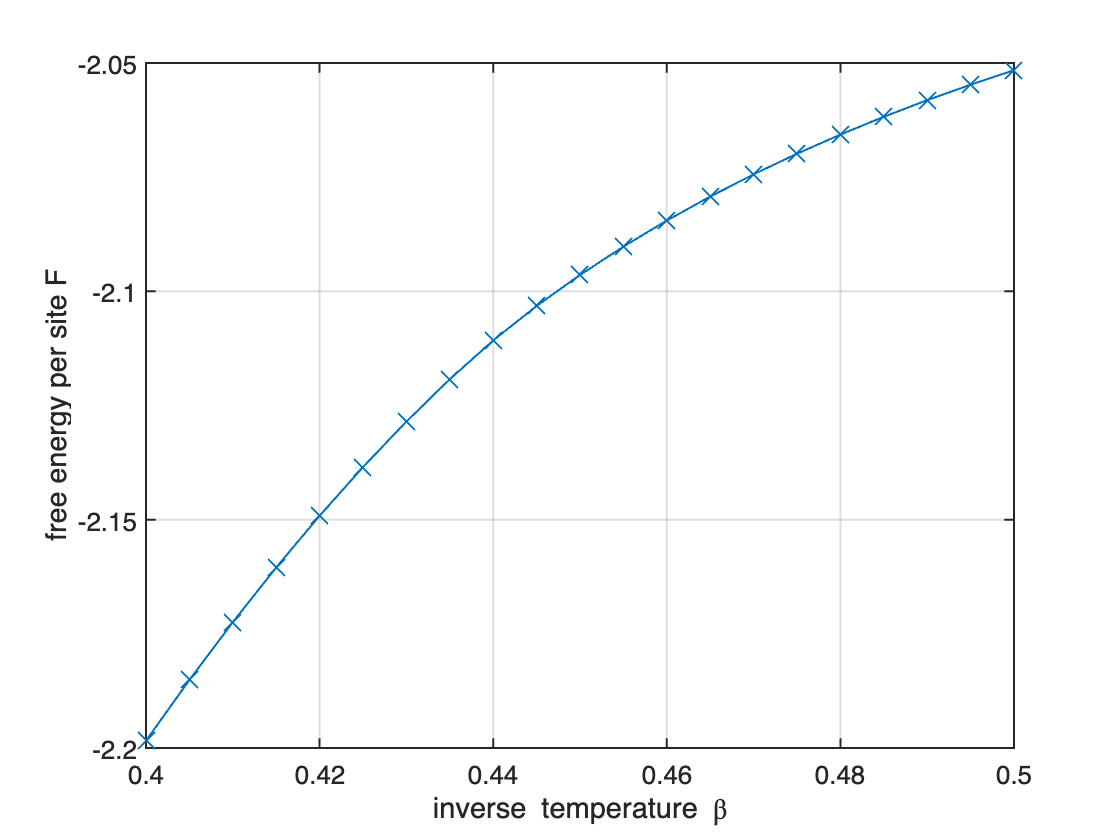

betas = (0.4:5e-3:0.5).';
Fexact = zeros(numel(betas),1);

for itb = (1:numel(betas))
    Fexact(itb) = -(log(2)/2 + (1/2/pi)*integral(@(x) ...
        log(cosh(2*betas(itb))^2 + sinh(2*betas(itb))* ...
        sqrt(sinh(2*betas(itb))^2 + sinh(2*betas(itb))^(-2) ...
        - 2*cos(2*x))), 0,pi))/betas(itb);
end

figure;
plot(betas,Fexact,'LineWidth',1,'Marker','x','MarkerSize',12);
set(gca,'LineWidth',1,'FontSize',13);
grid on;
xlabel('inverse temperature \beta');
ylabel('free energy per site F');

## Exercise (a): Complete the function for the symmetric CTMRG

There is a function `symCTMRG_Ex.m`, which is in the same sub-directory with this script. It is supposed to perform the symmetric CTMRG calculation on an iPEPS on a square lattice, which is defined by using a 1 x 1 unit cell. Due to the inversion symmetries, there are only one independent corner tensor and one independent transfer tensor. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

Now we perform the CTMRG calculations.

Nkeep = 20;
Fctm = zeros(numel(betas),1);
Cvs = cell(numel(betas),1); % information on the corner tensors

for itb = (1:numel(betas))
    M1 = zeros(2,2,2);
    M1(:,:,1) = sqrt(cosh(betas(itb)/2))*eye(2);
    M1(:,:,2) = sqrt(sinh(betas(itb)/2))*diag([1;-1]);
    M1 = permute(M1,[1 3 2]);

    % contract four rank-3 tensors
    M = M1;
    for itl = (1:3)
        M = contract(M,2+itl,2+itl,M1,3,1);
    end
    % project the last leg onto |up>+|down>
    M = contract(M,6,6,[1;1],2,1);
    % permute so that the legs are left-up-physical-down-right
    M = permute(M,[2 3 1 4 5]);

    [~, ~, sqnorm, Cvs{itb}] = symCTMRG_Ex (M,Nkeep);
    Fctm(itb) = -log(sqnorm)/betas(itb);
end

22-11-16 00:55:17 | Symmetric CTMRG with Nkeep = 20
22-11-16 00:55:17 | Converged after #97
Elapsed time: 0.1312s, CPU time: 1.36s, Avg # of cores: 10.36
22-11-16 00:55:17 | Memory usage : 4.17GiB
22-11-16 00:55:17 | Symmetric CTMRG with Nkeep = 20
22-11-16 00:55:17 | Converged after #109
Elapsed time: 0.1282s, CPU time: 1.5s, Avg # of cores: 11.7
22-11-16 00:55:17 | Memory usage : 4.18GiB
22-11-16 00:55:17 | Symmetric CTMRG with Nkeep = 20
22-11-16 00:55:18 | Converged after #126
Elapsed time: 0.1496s, CPU time: 1.76s, Avg # of cores: 11.77
22-11-16 00:55:18 | Memory usage : 4.18GiB
22-11-16 00:55:18 | Symmetric CTMRG with Nkeep = 20
22-11-16 00:55:18 | Converged after #149
Elapsed time: 0.1766s, CPU time: 2.1s, Avg # of cores: 11.89
22-11-16 00:55:18 | Memory usage : 4.18GiB
22-11-16 00:55:18 | Symmetric CTMRG with Nkeep = 20
22-11-16 00:55:18 | Converged after #182
Elapsed time: 0.2282s, CPU time: 2.81s, Avg # of cores: 12.31
22-11-16 00:55:18 | Memory usage : 4.18GiB
22-11-16 00:55

We find that the error of the CTMRG result is largest and also the convergence is slowest near $\beta$ = 0.44.

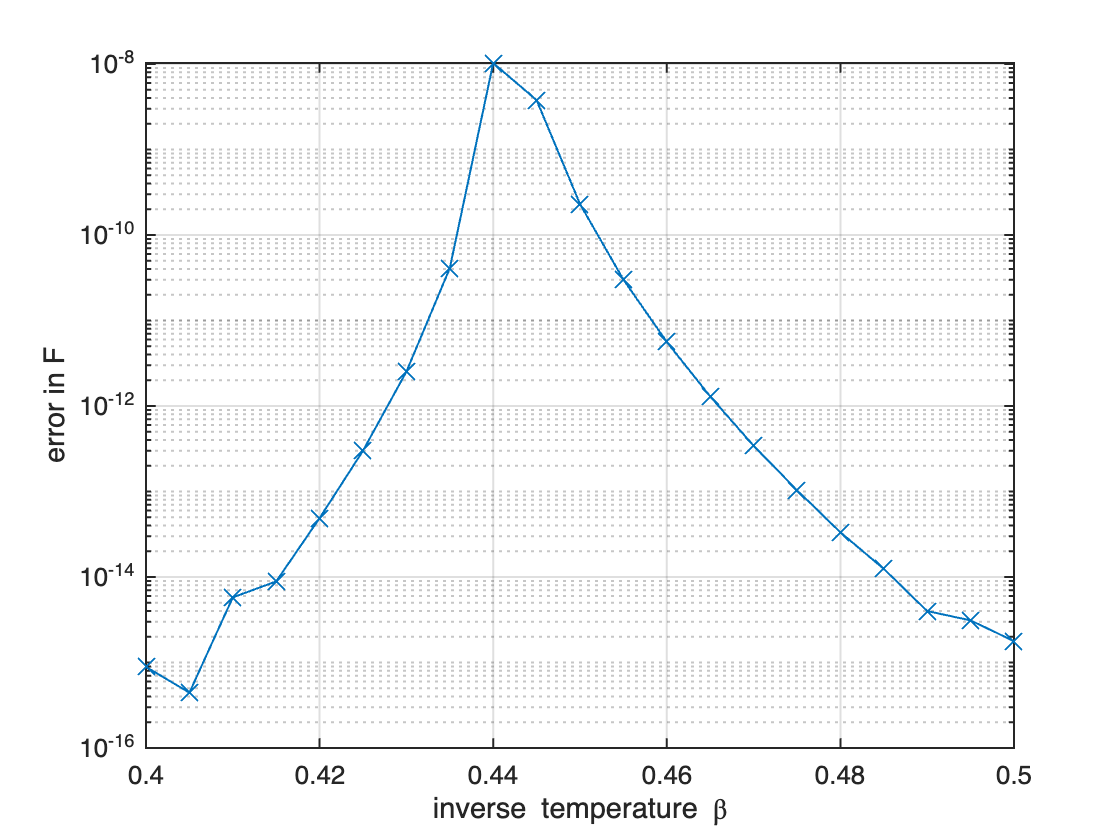

figure;
plot(betas,abs(Fctm-Fexact),'LineWidth',1,'Marker','x','MarkerSize',12);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('inverse temperature \beta');
ylabel('error in F');

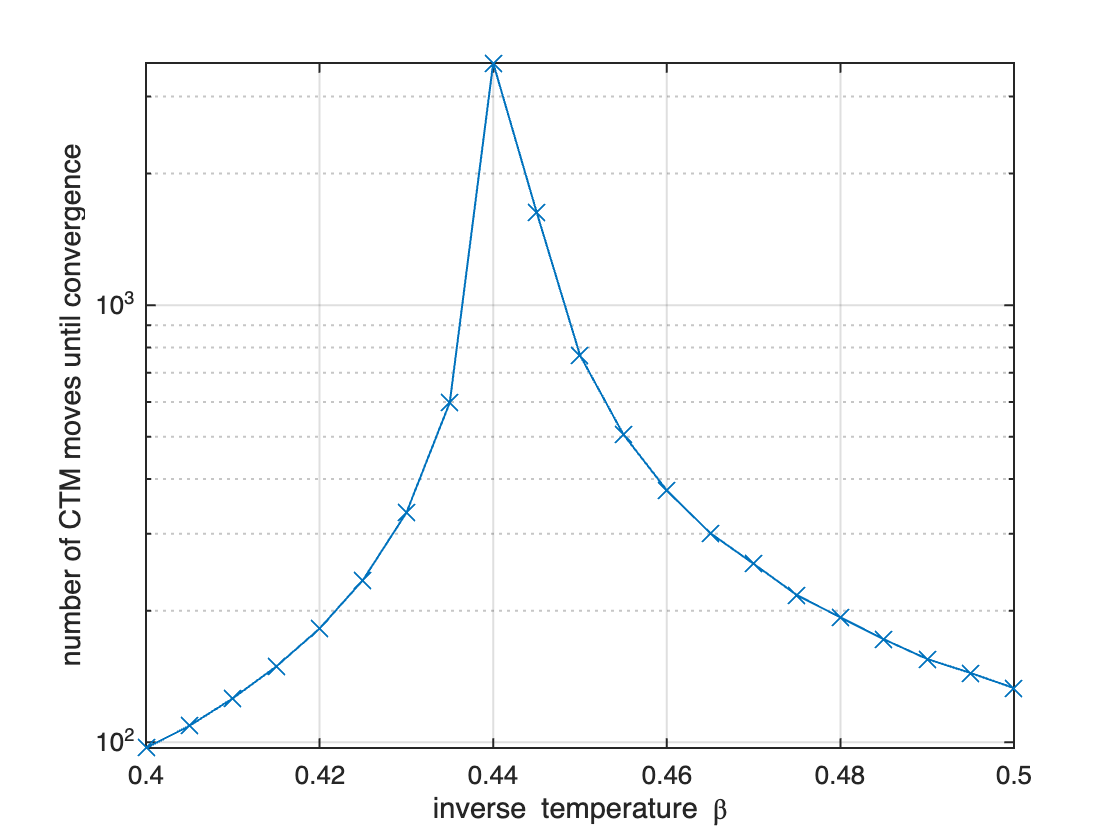

figure;
plot(betas,cellfun(@(x) size(x,2), Cvs),'LineWidth',1,'Marker','x','MarkerSize',12);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('inverse temperature \beta');
ylabel('number of CTM moves until convergence');

What happens near $\beta$ = 0.44? Actually, there is a (classical) phase transition at $\beta_c = \ln (1+\sqrt{2}) /2$ at which correlation functions become polynomially decaying, i.e., long-ranged. As a result, the PEPS becomes strongly entangled if its parameter $\beta$ is close to $\beta_c$.

fprintf('%.7g\n',log(1+sqrt(2))/2);

0.4406868


The diagonal elements (or equivalently, eigenvalues) of the corner tensor also reflect the phase transition. Let's plot how those elements converge with iterations, for different values of $\beta$.

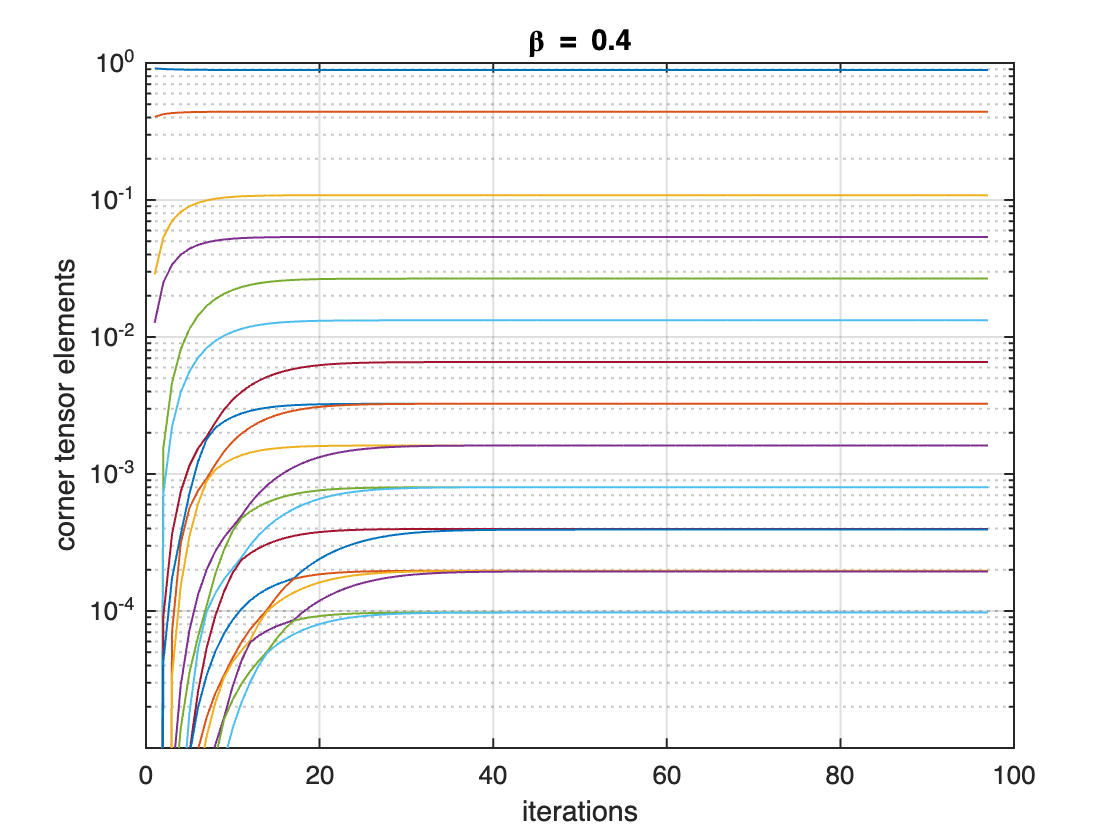

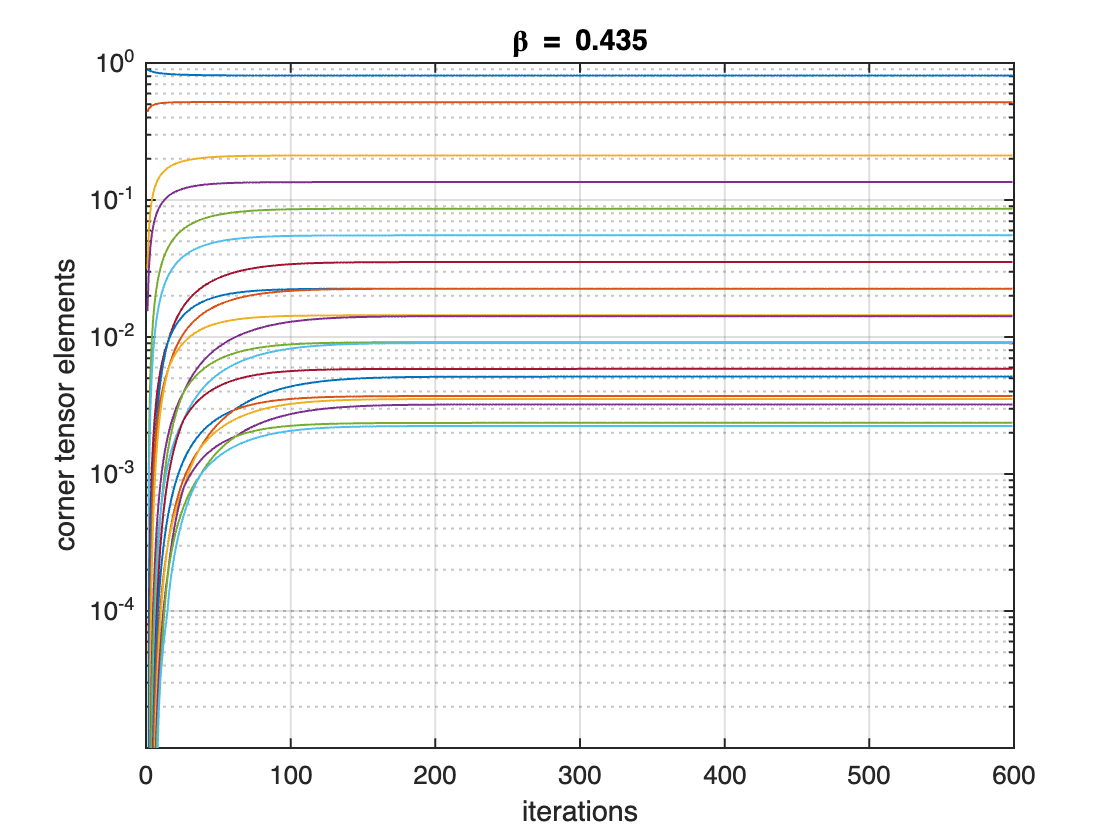

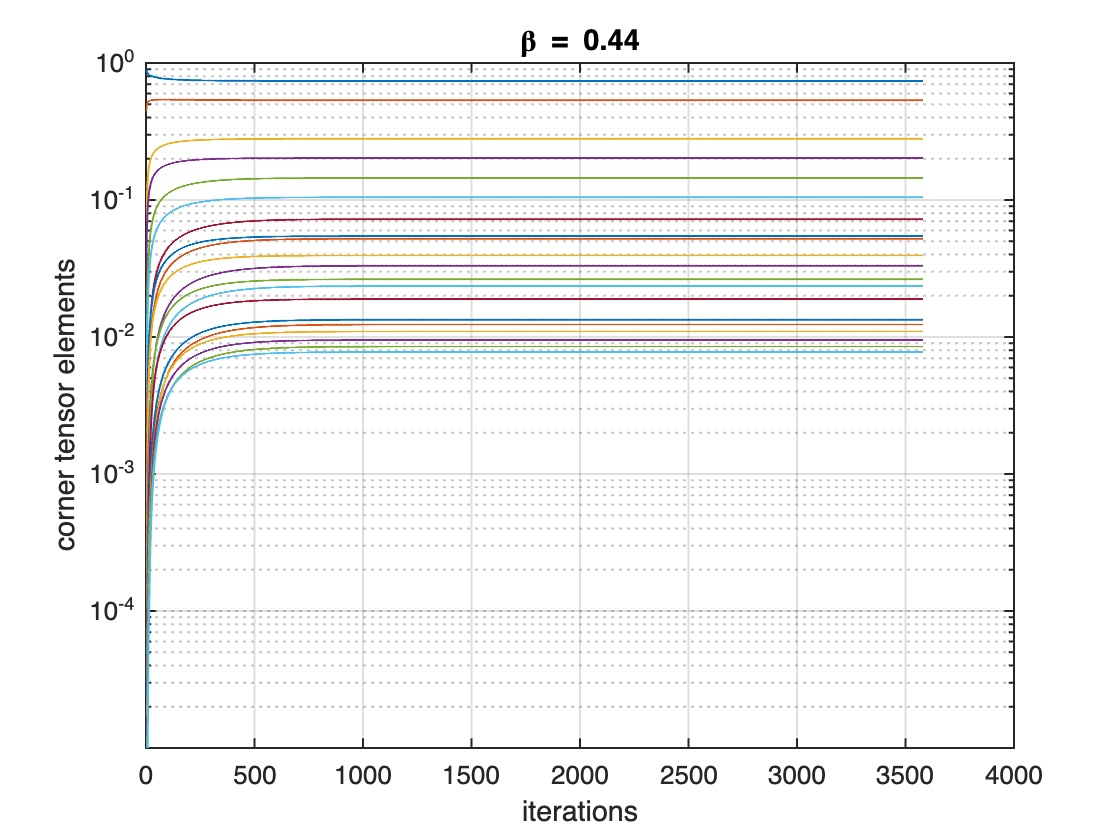

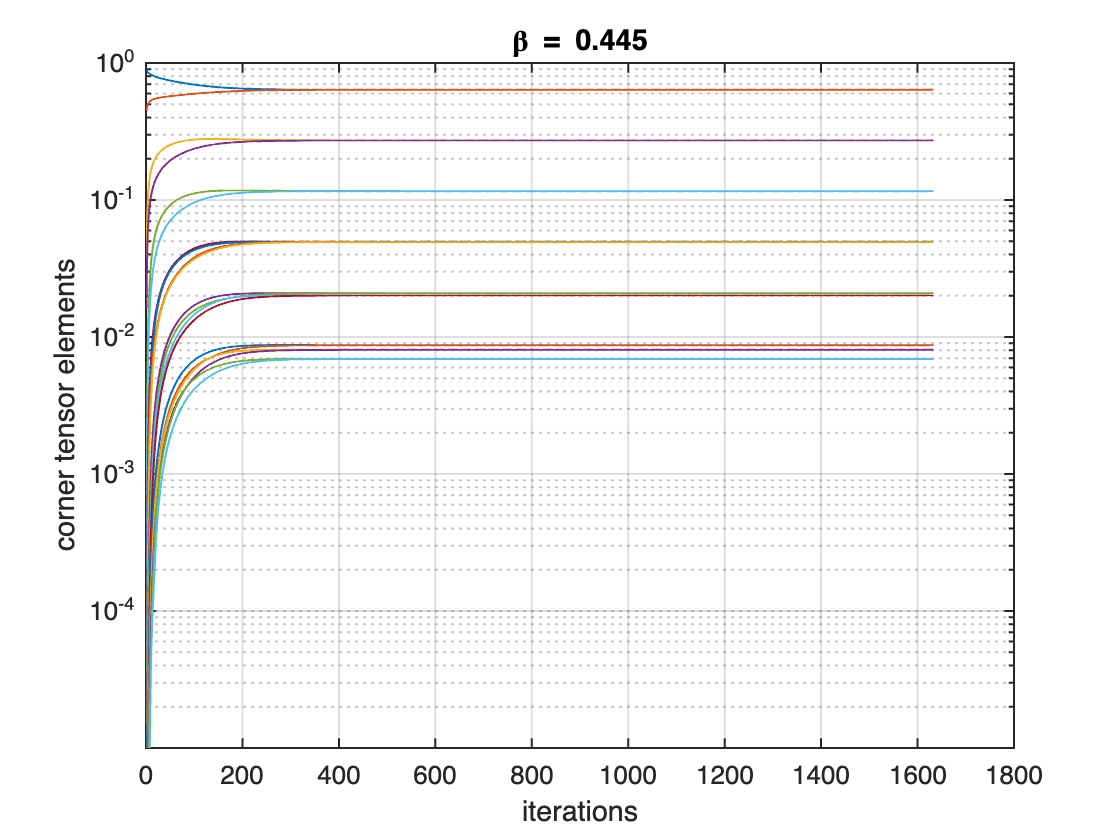

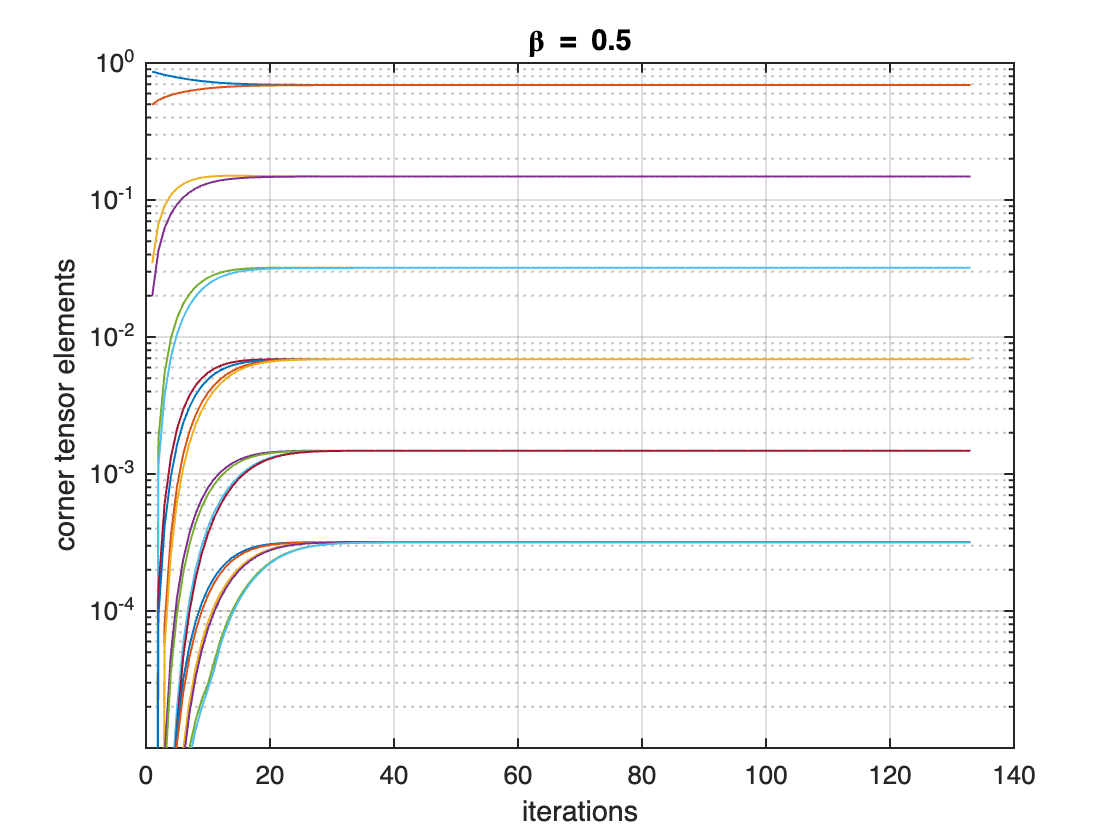

itbs = [1 8 9 10 21];
for itb = itbs
    figure;
    plot((1:size(Cvs{itb},2)).',Cvs{itb}.','LineWidth',1);
    set(gca,'YScale','log','LineWidth',1,'FontSize',13);
    grid on;
    xlabel('iterations');
    ylabel('corner tensor elements');
    ylim([1e-5 1]);
    title(['\beta = ',sprintf('%.4g',betas(itb))]);
end

We see the following features:

- The largest eigenvalues are non-degenerate for $\beta < \beta_c$, while there are even-fold degeneracies for $\beta > \beta_c$.

- For given $\beta$ separated from $\beta_c$, the eigenvalues are exponentially decaying, so only a small number of the largest eigenvalues dominate. On the other hand, for $\beta \approx \beta_c$, the eigenvalues don't decay quickly and many of them are important; hence larger error and longer time to converge.